# Semantic Segmentation Using Deep Learning

This example shows how to train a semantic segmentation network using deep learning. 

A semantic segmentation network classifies every pixel in an image, resulting in an image that is segmented by class. Applications for semantic segmentation include road segmentation for autonomous driving and cancer cell segmentation for medical diagnosis. To learn more, see [Semantic Segmentation](docid:vision_ug#mw_1d343c03-9e01-4466-be83-06053df3f8a0).

To illustrate the training procedure, this example trains Deeplab v3+ [1], one type of convolutional neural network (CNN) designed for semantic image segmentation. Other types of networks for semantic segmentation include fully convolutional networks (FCN), SegNet, and U-Net. The training procedure shown here can be applied to those networks too.

This example uses the [CamVid dataset](http://web4.cs.ucl.ac.uk/staff/g.brostow/MotionSegRecData/) [2] from the University of Cambridge for training. This dataset is a collection of images containing street-level views obtained while driving. The dataset provides pixel-level labels for 32 semantic classes including car, pedestrian, and road.

## Setup

This example creates the Deeplab v3+ network with weights initialized from a pre-trained Resnet-18 network. ResNet-18 is an efficient network that is well suited for applications with limited processing resources. Other pretrained networks such as MobileNet v2 or ResNet-50 can also be used depending on application requirements. For more details, see [Pretrained Deep Neural Networks](docid:nnet_ug#bvf9ych-1).

To get a pretrained Resnet-18, install [Deep Learning Toolbox™ Model for Resnet-18 Network](docid:nnet_ref#mw_591a2746-7267-4890-8390-87ae4dc7204c). After installation is complete, run the following code to verify that the installation is correct.

resnet18();

In addition, download a pretrained version of DeepLab v3+. The pretrained model allows you to run the entire example without having to wait for training to complete.

pretrainedURL = 'https://www.mathworks.com/supportfiles/vision/data/deeplabv3plusResnet18CamVid.mat';
pretrainedFolder = fullfile(".",'pretrainedNetwork');
onlinePretrainedNetwork = fullfile(pretrainedFolder,'deeplabv3plusResnet18CamVid.mat'); 
localPretrainedNetwork = fullfile(pretrainedFolder,'resnet18CamVid_latest.mat');
if ~exist(onlinePretrainedNetwork,'file')
    mkdir(pretrainedFolder);
    disp('Downloading pretrained network (58 MB)...');
    websave(onlinePretrainedNetwork,pretrainedURL);
end

A CUDA-capable NVIDIA™ GPU is highly recommended for running this example. Use of a GPU requires Parallel Computing Toolbox™. For information about the supported compute capabilities, see [GPU Support by Release](docid:distcomp_ug#mw_57e04559-0b60-42d5-ad55-e77ec5f5865f).

## Download CamVid Dataset

Download the CamVid dataset from the following URLs.

imageURL = 'http://web4.cs.ucl.ac.uk/staff/g.brostow/MotionSegRecData/files/701_StillsRaw_full.zip';
labelURL = 'http://web4.cs.ucl.ac.uk/staff/g.brostow/MotionSegRecData/data/LabeledApproved_full.zip';
 
outputFolder = fullfile('CamVid'); 
labelsZip = fullfile(outputFolder,'labels.zip');
imagesZip = fullfile(outputFolder,'images.zip');

if ~exist(labelsZip, 'file') || ~exist(imagesZip,'file')   
    mkdir(outputFolder)
       
    disp('Downloading 16 MB CamVid dataset labels...'); 
    websave(labelsZip, labelURL);
    unzip(labelsZip, fullfile(outputFolder,'labels'));
    
    disp('Downloading 557 MB CamVid dataset images...');  
    websave(imagesZip, imageURL);       
    unzip(imagesZip, fullfile(outputFolder,'images'));    
end

Note: Download time of the data depends on your Internet connection. The commands used above block MATLAB until the download is complete. Alternatively, you can use your web browser to first download the dataset to your local disk. To use the file you downloaded from the web, change the `outputFolder` variable above to the location of the downloaded file.

## Load CamVid Images

Use [`imageDatastore`](docid:matlab_ref#butueui-1) to load CamVid images. The  `imageDatastore` enables you to efficiently load a large collection of images on disk.

imgDir = fullfile(outputFolder,'images','701_StillsRaw_full');
imds = imageDatastore(imgDir);

Display one of the images.

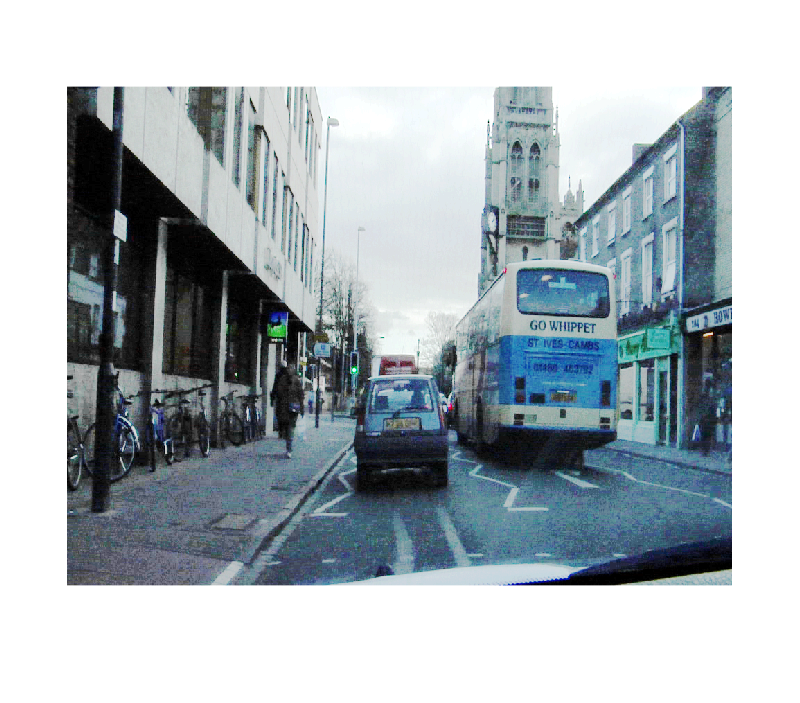

I = readimage(imds,4);
I = histeq(I);
imshow(I)

## Load CamVid Pixel-Labeled Images

Use [`pixelLabelDatastore`](docid:vision_ref.mw_c2246553-ba4a-4bad-aad4-6ab8fa2f7f2d) to load CamVid pixel label image data. A `pixelLabelDatastore` encapsulates the pixel label data and the label ID to a class name mapping.

We make training easier, we group the 32 original classes in CamVid to 11 classes. Specify these classes.

classes = [
    "Sky"
    "Building"
    "Pole"
    "Road"
    "Pavement"
    "Tree"
    "SignSymbol"
    "Fence"
    "Car"
    "Pedestrian"
    "Bicyclist"
    ];

To reduce 32 classes into 11, multiple classes from the original dataset are grouped together. For example, "Car" is a combination of "Car", "SUVPickupTruck", "Truck_Bus", "Train", and "OtherMoving". Return the grouped label IDs by using the supporting function `camvidPixelLabelIDs`, which is listed at the end of this example.

labelIDs = camvidPixelLabelIDs();

Use the classes and label IDs to create the `pixelLabelDatastore.`

labelDir = fullfile(outputFolder,'labels');
pxds = pixelLabelDatastore(labelDir,classes,labelIDs);

Read and display one of the pixel-labeled images by overlaying it on top of an image.

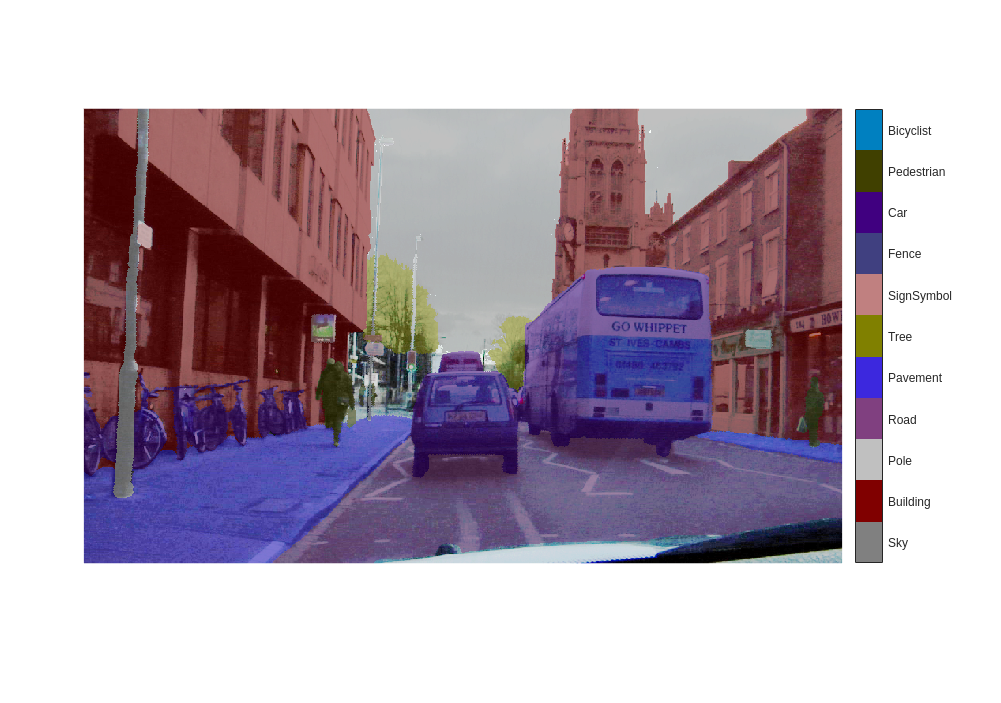

C = readimage(pxds,4);
cmap = camvidColorMap;
B = labeloverlay(I,C,'ColorMap',cmap);
imshow(B)
pixelLabelColorbar(cmap,classes);

Areas with no color overlay do not have pixel labels and are not used during training.

## Analyze Dataset Statistics

To see the distribution of class labels in the CamVid dataset, use [countEachLabel](docid:vision_ref#mw_1c600e69-1a15-4538-9629-7bceaafbd4e7). This function counts the number of pixels by class label.

tbl = countEachLabel(pxds)

tbl = 11×3 table
         Name         PixelCount    ImagePixelCount
    ______________    __________    _______________

    {'Sky'       }    7.6801e+07      4.8315e+08   
    {'Building'  }    1.1737e+08      4.8315e+08   
    {'Pole'      }    4.7987e+06      4.8315e+08   
    {'Road'      }    1.4054e+08      4.8453e+08   
    {'Pavement'  }    3.3614e+07      4.7209e+08   
    {'Tree'      }    5.4259e+07       4.479e+08   
    {'SignSymbol'}    5.2242e+06      4.6863e+08   
    {'Fence'     }    6.9211e+06       2.516e+08   
    {'Car'       }    2.4437e+07      4.8315e+08   
    {'Pedestrian'}    3.4029e+06      4.4444e+08   
    {'Bicyclist' }    2.5912e+06      2.6196e+08   


Visualize the pixel counts by class.

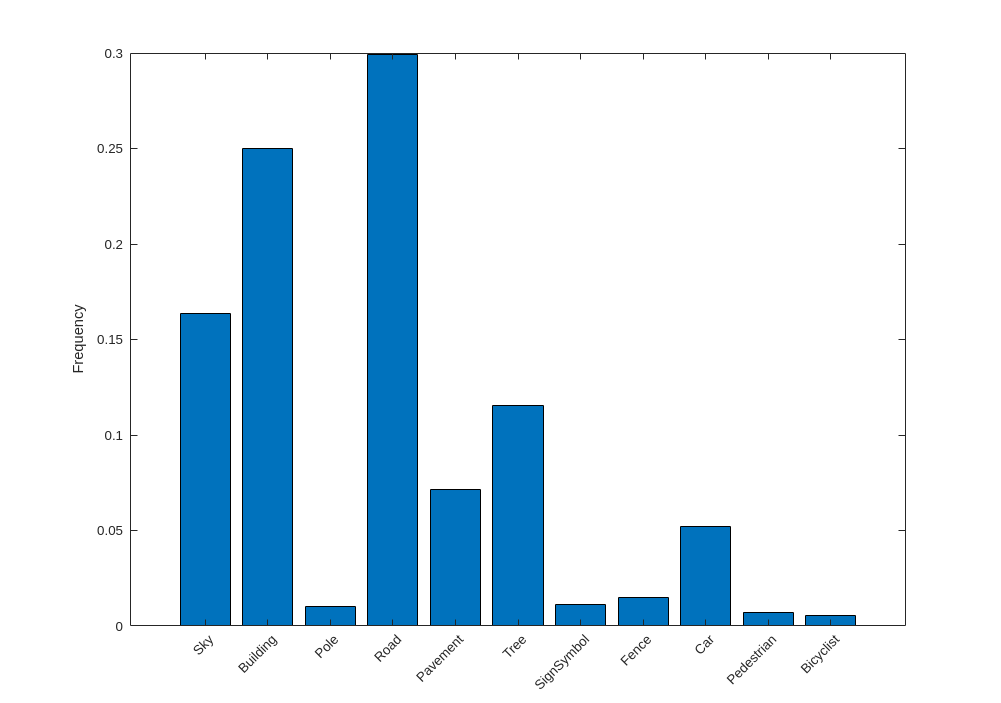

frequency = tbl.PixelCount/sum(tbl.PixelCount);

bar(1:numel(classes),frequency)
xticks(1:numel(classes)) 
xticklabels(tbl.Name)
xtickangle(45)
ylabel('Frequency')

Ideally, all classes would have an equal number of observations. However, the classes in CamVid are imbalanced, which is a common issue in automotive data-sets of street scenes. Such scenes have more sky, building, and road pixels than pedestrian and bicyclist pixels because sky, buildings and roads cover more area in the image. If not handled correctly, this imbalance can be detrimental to the learning process because the learning is biased in favor of the dominant classes. Later on in this example, you will use class weighting to handle this issue.

The images in the CamVid data set are 720 by 960 in size. Image size is chosen such that a large enough batch of images can fit in memory during training on an NVIDIA™ Titan X with 12 GB of memory. You may need to resize the images to smaller sizes if your GPU does not have sufficient memory or reduce the training batch size.

## Prepare Training, Validation, and Test Sets

Deeplab v3+ is trained using 60% of the images from the dataset. The rest of the images are split evenly in 20% and 20% for validation and testing respectively. The following code randomly splits the image and pixel label data into a training, validation and test set.


[imdsTrain, imdsVal, imdsTest, pxdsTrain, pxdsVal, pxdsTest] = partitionCamVidData(imds,pxds);

The 60/20/20 split results in the following number of training, validation and test images:

numTrainingImages = numel(imdsTrain.Files)

numTrainingImages = 421

numValImages = numel(imdsVal.Files)

numValImages = 140

numTestingImages = numel(imdsTest.Files)

numTestingImages = 140

## Create the Network

Use the `deeplabv3plusLayers` function to create a DeepLab v3+ network based on ResNet-18. Choosing the best network for your application requires empirical analysis and is another level of hyperparameter tuning. For example, you can experiment with different base networks such as ResNet-50 or MobileNet v2, or you can try other semantic segmentation network architectures such as SegNet, fully convolutional networks (FCN), or U-Net.

% Specify the network image size. This is typically the same as the traing image sizes.
imageSize = [720 960 3];

% Specify the number of classes.
numClasses = numel(classes);

% Create DeepLab v3+.
lgraph = deeplabv3plusLayers(imageSize, numClasses, "resnet18");

## Balance Classes Using Class Weighting

As shown earlier, the classes in CamVid are not balanced. To improve training, you can use class weighting to balance the classes. Use the pixel label counts computed earlier with [countEachLabel](docid:vision_ref#mw_1c600e69-1a15-4538-9629-7bceaafbd4e7) and calculate the median frequency class weights.

imageFreq = tbl.PixelCount ./ tbl.ImagePixelCount;
classWeights = median(imageFreq) ./ imageFreq

classWeights =     0.3182
    0.2082
    5.0924
    0.1744
    0.7103
    0.4175
    4.5371
    1.8386
    1.0000
    6.6059


Specify the class weights using a [ `pixelClassificationLayer`](docid:vision_ref.mw_783aebd8-1ff1-4bc6-8508-90c8b71fca32).

pxLayer = pixelClassificationLayer('Name','labels','Classes',tbl.Name,'ClassWeights',classWeights);
lgraph = replaceLayer(lgraph,"classification",pxLayer);

## Select Training Options

The optimization algorithm used for training is stochastic gradient descent with momentum (SGDM). Use [`trainingOptions`](docid:nnet_ref.bu59f0q) to specify the hyper-parameters used for SGDM.

% Define validation data.
dsVal = combine(imdsVal,pxdsVal);

% Define training options. 
options = trainingOptions('sgdm', ...
    'LearnRateSchedule','piecewise',...
    'LearnRateDropPeriod',10,...
    'LearnRateDropFactor',0.3,...
    'Momentum',0.9, ...
    'InitialLearnRate',1e-3, ...
    'L2Regularization',0.005, ...
    'ValidationData',dsVal,...
    'MaxEpochs',30, ...  
    'MiniBatchSize',8, ...
    'Shuffle','every-epoch', ...
    'CheckpointPath', tempdir, ...
    'VerboseFrequency',2,...
    'Plots','training-progress',...
    'ValidationPatience', 4);

The learning rate uses a piecewise schedule. The learning rate is reduced by a factor of 0.3 every 10 epochs. This allows the network to learn quickly with a higher initial learning rate, while being able to find a solution close to the local optimum once the learning rate drops.

The network is tested against the validation data every epoch by setting the `'ValidationData'` parameter. The `'ValidationPatience'` is set to 4 to stop training early when the validation accuracy converges. This prevents the network from overfitting on the training dataset.

A mini-batch size of 8 is used to reduce memory usage while training. You can increase or decrease this value based on the amount of GPU memory you have on your system.

In addition, `'CheckpointPath'` is set to a temporary location. This name-value pair enables the saving of network checkpoints at the end of every training epoch. If training is interrupted due to a system failure or power outage, you can resume training from the saved checkpoint. Make sure that the location specified by `'CheckpointPath'` has enough space to store the network checkpoints. For example, saving 100 Deeplab v3+ checkpoints requires ~6 GB of disk space because each checkpoint is 61 MB.

## Data Augmentation

Data augmentation is used to improve network accuracy by randomly transforming the original data during training. By using data augmentation, you can add more variety to the training data without increasing the number of labeled training samples. To apply the same random transformation to both image and pixel label data use datastore `combine` and `transform`. First, combine `imdsTrain` and `pxdsTrain`.

dsTrain = combine(imdsTrain, pxdsTrain);

Next, use datastore `transform` to apply the desired data augmentation defined in the supporting function `augmentImageAndLabel`. Here, random left/right reflection and random X/Y translation of +/- 10 pixels is used for data augmentation. 

xTrans = [-10 10];
yTrans = [-10 10];
dsTrain = transform(dsTrain, @(data)augmentImageAndLabel(data,xTrans,yTrans));

Note that data augmentation is not applied to the test and validation data. Ideally, test and validation data should be representative of the original data and is left unmodified for unbiased evaluation.

## Start Training

Start training using [`trainNetwork`](docid:nnet_ref#bu6sn4c) if the `doTraining` flag is true. Otherwise, load a pretrained network.

Note: The training was verified on an NVIDIA™ Titan X with 12 GB of GPU memory. If your GPU has less memory, you may run out of memory during training. If this happens, try setting `'MiniBatchSize'` to 1 in `trainingOptions`, or reducing the network input and resizing the training data. Training this network takes about 5 hours. Depending on your GPU hardware, it can take even longer.

doTraining = false;
if doTraining    
    [net, info] = trainNetwork(dsTrain,lgraph,options);
    save SemanticSegmentationUsingDeepLearningExample/pretrainedNetwork/resnet18CamVid_latest.mat net info metrics
else
    data = load(localPretrainedNetwork); 
    net = data.net;
end


## Test Network on One Image

As a quick sanity check, run the trained network on one test image. 

I = readimage(imdsTest,35);
C = semanticseg(I, net);

Display the results.

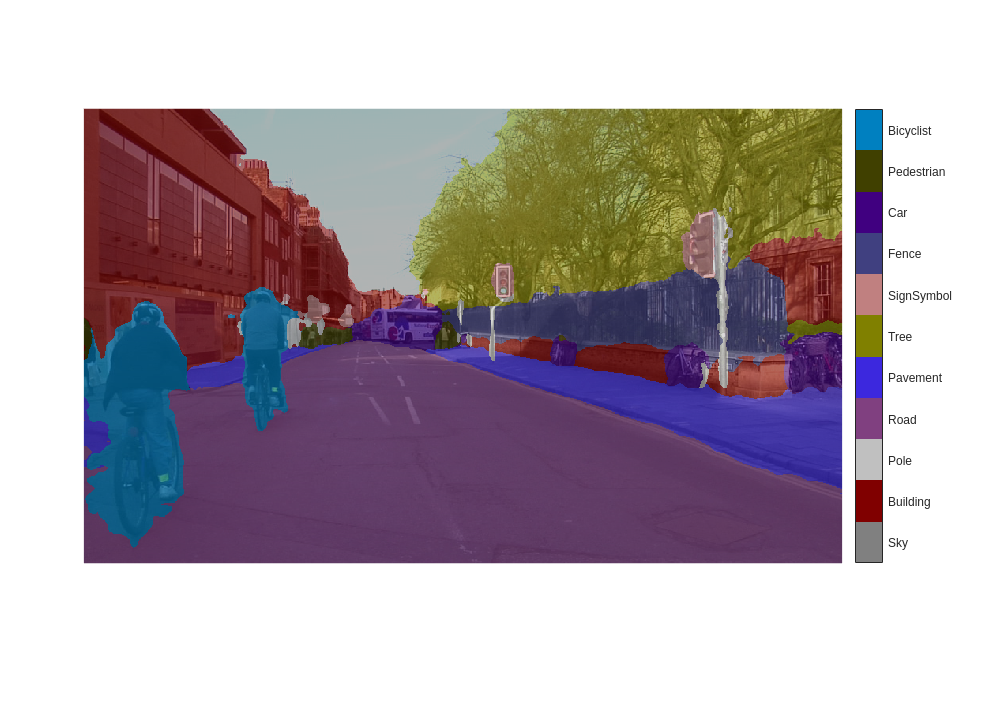

B = labeloverlay(I,C,'Colormap',cmap,'Transparency',0.4);
imshow(B)
pixelLabelColorbar(cmap, classes);

Compare the results in `C` with the expected ground truth stored in `pxdsTest`. The green and magenta regions highlight areas where the segmentation results differ from the expected ground truth.

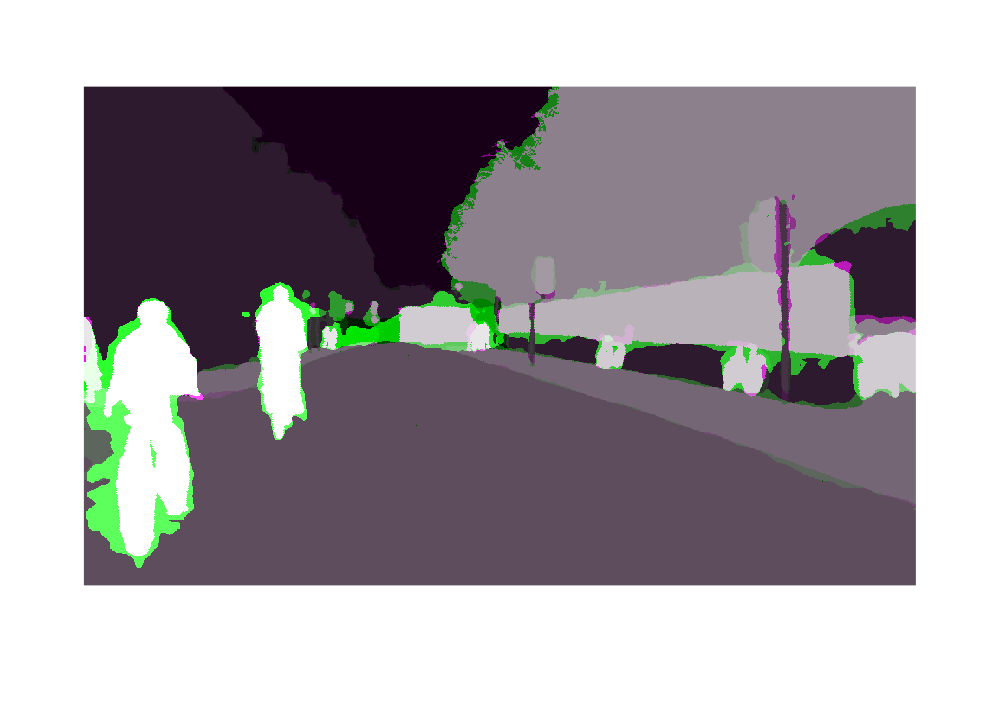

expectedResult = readimage(pxdsTest,35);
actual = uint8(C);
expected = uint8(expectedResult);
imshowpair(actual, expected)

Visually, the semantic segmentation results overlap well for classes such as road, sky, and building. However, smaller objects like pedestrians and cars are not as accurate. The amount of overlap per class can be measured using the intersection-over-union (IoU) metric, also known as the Jaccard index. Use the  [`jaccard`](docid:images_ref.mw_fc8c8913-3141-4127-abf4-c7d90c72c870) function to measure IoU.

iou = jaccard(C,expectedResult);
table(classes,iou)

ans = 11×2 table
      classes         iou  
    ____________    _______

    "Sky"           0.93363
    "Building"       0.8693
    "Pole"          0.39034
    "Road"          0.94383
    "Pavement"      0.84702
    "Tree"          0.91911
    "SignSymbol"    0.62602
    "Fence"         0.81795
    "Car"           0.71657
    "Pedestrian"    0.33752
    "Bicyclist"     0.69629


The IoU metric confirms the visual results. Road, sky, and building classes have high IoU scores, while classes such as pedestrian and car have low scores. Other common segmentation metrics include the [Dice index](docid:images_ref#mw_1ee709d7-bf6b-4ac9-8f5d-e7caf72497d4) and the [Boundary-F1](docid:images_ref#mw_53845c75-154c-4cbe-99c2-54ef222fecd7) contour matching score.

## Evaluate Trained Network

To measure accuracy for multiple test images, run[ semanticseg](docid:vision_ref#mw_bbecb1af-a6c9-43d1-91f5-48607edc15d1) on the entire test set. A mini-batch size of 4 is used to reduce memory usage while segmenting images. You can increase or decrease this value based on the amount of GPU memory you have on your system. 

pxdsResults = semanticseg(imdsTest,net, ...
    'MiniBatchSize',4, ...
    'WriteLocation',tempdir, ...
    'Verbose',false);

`semanticseg` returns the results for the test set as a `pixelLabelDatastore` object. The actual pixel label data for each test image in `imdsTest` is written to disk in the location specified by the `'WriteLocation'` parameter. Use [ `evaluateSemanticSegmentation`](docid:vision_ref.mw_ec14c36c-b93d-4fde-8512-ea7d51651b89) to measure semantic segmentation metrics on the test set results. 

metrics = evaluateSemanticSegmentation(pxdsResults,pxdsTest,'Verbose',false);

`evaluateSemanticSegmentation` returns various metrics for the entire dataset, for individual classes, and for each test image. To see the dataset level metrics, inspect `metrics.DataSetMetrics` .

metrics.DataSetMetrics

ans = 1×5 table
    GlobalAccuracy    MeanAccuracy    MeanIoU    WeightedIoU    MeanBFScore
    ______________    ____________    _______    ___________    ___________

       0.89241          0.86566       0.66396      0.82833        0.69226  


The dataset metrics provide a high-level overview of the network performance. To see the impact each class has on the overall performance, inspect the per-class metrics using `metrics.ClassMetrics`.

metrics.ClassMetrics

ans = 11×3 table
                  Accuracy      IoU      MeanBFScore
                  ________    _______    ___________

    Sky            0.9425     0.90963      0.90745  
    Building      0.81429     0.79131      0.63899  
    Pole          0.76018     0.24602      0.58423  
    Road          0.93978     0.92651      0.80588  
    Pavement      0.89985     0.73855       0.7453  
    Tree          0.88272     0.77461      0.72946  
    SignSymbol     0.7657     0.42316      0.53585  
    Fence         0.83675     0.57704       0.5504  
    Car           0.92624     0.79431      0.74323  
    Pedestrian    0.86365     0.47024      0.64146  
    Bicyclist     0.89059     0.65221      0.59571  


Although the overall dataset performance is quite high, the class metrics show that underrepresented classes such as `Pedestrian`, `Bicyclist`, and `Car` are not segmented as well as classes such as `Road`, `Sky`, and `Building`. Additional data that includes more samples of the underrepresented classes might help improve the results.

## Supporting Functions

function labelIDs = camvidPixelLabelIDs()
% Return the label IDs corresponding to each class.
%
% The CamVid dataset has 32 classes. Group them into 11 classes following
% the original SegNet training methodology [1].
%
% The 11 classes are:
%   "Sky" "Building", "Pole", "Road", "Pavement", "Tree", "SignSymbol",
%   "Fence", "Car", "Pedestrian",  and "Bicyclist".
%
% CamVid pixel label IDs are provided as RGB color values. Group them into
% 11 classes and return them as a cell array of M-by-3 matrices. The
% original CamVid class names are listed alongside each RGB value. Note
% that the Other/Void class are excluded below.
labelIDs = { ...
    
    % "Sky"
    [
    128 128 128; ... % "Sky"
    ]
    
    % "Building" 
    [
    000 128 064; ... % "Bridge"
    128 000 000; ... % "Building"
    064 192 000; ... % "Wall"
    064 000 064; ... % "Tunnel"
    192 000 128; ... % "Archway"
    ]
    
    % "Pole"
    [
    192 192 128; ... % "Column_Pole"
    000 000 064; ... % "TrafficCone"
    ]
    
    % Road
    [
    128 064 128; ... % "Road"
    128 000 192; ... % "LaneMkgsDriv"
    192 000 064; ... % "LaneMkgsNonDriv"
    ]
    
    % "Pavement"
    [
    000 000 192; ... % "Sidewalk" 
    064 192 128; ... % "ParkingBlock"
    128 128 192; ... % "RoadShoulder"
    ]
        
    % "Tree"
    [
    128 128 000; ... % "Tree"
    192 192 000; ... % "VegetationMisc"
    ]
    
    % "SignSymbol"
    [
    192 128 128; ... % "SignSymbol"
    128 128 064; ... % "Misc_Text"
    000 064 064; ... % "TrafficLight"
    ]
    
    % "Fence"
    [
    064 064 128; ... % "Fence"
    ]
    
    % "Car"
    [
    064 000 128; ... % "Car"
    064 128 192; ... % "SUVPickupTruck"
    192 128 192; ... % "Truck_Bus"
    192 064 128; ... % "Train"
    128 064 064; ... % "OtherMoving"
    ]
    
    % "Pedestrian"
    [
    064 064 000; ... % "Pedestrian"
    192 128 064; ... % "Child"
    064 000 192; ... % "CartLuggagePram"
    064 128 064; ... % "Animal"
    ]
    
    % "Bicyclist"
    [
    000 128 192; ... % "Bicyclist"
    192 000 192; ... % "MotorcycleScooter"
    ]
    
    };
end


function pixelLabelColorbar(cmap, classNames)
% Add a colorbar to the current axis. The colorbar is formatted
% to display the class names with the color.

colormap(gca,cmap)

% Add colorbar to current figure.
c = colorbar('peer', gca);

% Use class names for tick marks.
c.TickLabels = classNames;
numClasses = size(cmap,1);

% Center tick labels.
c.Ticks = 1/(numClasses*2):1/numClasses:1;

% Remove tick mark.
c.TickLength = 0;
end

function cmap = camvidColorMap()
% Define the colormap used by CamVid dataset.

cmap = [
    128 128 128   % Sky
    128 0 0       % Building
    192 192 192   % Pole
    128 64 128    % Road
    60 40 222     % Pavement
    128 128 0     % Tree
    192 128 128   % SignSymbol
    64 64 128     % Fence
    64 0 128      % Car
    64 64 0       % Pedestrian
    0 128 192     % Bicyclist
    ];

% Normalize between [0 1].
cmap = cmap ./ 255;
end

function [imdsTrain, imdsVal, imdsTest, pxdsTrain, pxdsVal, pxdsTest] = partitionCamVidData(imds,pxds)
% Partition CamVid data by randomly selecting 60% of the data for training. The
% rest is used for testing.
    
% Set initial random state for example reproducibility.
rng(0); 
numFiles = numel(imds.Files);
shuffledIndices = randperm(numFiles);

% Use 60% of the images for training.
numTrain = round(0.60 * numFiles);
trainingIdx = shuffledIndices(1:numTrain);

% Use 20% of the images for validation
numVal = round(0.20 * numFiles);
valIdx = shuffledIndices(numTrain+1:numTrain+numVal);

% Use the rest for testing.
testIdx = shuffledIndices(numTrain+numVal+1:end);

% Create image datastores for training and test.
trainingImages = imds.Files(trainingIdx);
valImages = imds.Files(valIdx);
testImages = imds.Files(testIdx);

imdsTrain = imageDatastore(trainingImages);
imdsVal = imageDatastore(valImages);
imdsTest = imageDatastore(testImages);

% Extract class and label IDs info.
classes = pxds.ClassNames;
labelIDs = camvidPixelLabelIDs();

% Create pixel label datastores for training and test.
trainingLabels = pxds.Files(trainingIdx);
valLabels = pxds.Files(valIdx);
testLabels = pxds.Files(testIdx);

pxdsTrain = pixelLabelDatastore(trainingLabels, classes, labelIDs);
pxdsVal = pixelLabelDatastore(valLabels, classes, labelIDs);
pxdsTest = pixelLabelDatastore(testLabels, classes, labelIDs);
end

function data = augmentImageAndLabel(data, xTrans, yTrans)
% Augment images and pixel label images using random reflection and
% translation.

for i = 1:size(data,1)
    
    tform = randomAffine2d(...
        'XReflection',true,...
        'XTranslation', xTrans, ...
        'YTranslation', yTrans);
    
    % Center the view at the center of image in the output space while
    % allowing translation to move the output image out of view.
    rout = affineOutputView(size(data{i,1}), tform, 'BoundsStyle', 'centerOutput');
    
    % Warp the image and pixel labels using the same transform.
    data{i,1} = imwarp(data{i,1}, tform, 'OutputView', rout);
    data{i,2} = imwarp(data{i,2}, tform, 'OutputView', rout);
    
end
end

## References

[1] Chen, Liang-Chieh et al. “Encoder-Decoder with Atrous Separable Convolution for Semantic Image Segmentation.” ECCV (2018).

[2] Brostow, G. J., J. Fauqueur, and R. Cipolla. "Semantic object classes in video: A high-definition ground truth database." *Pattern Recognition Letters*. Vol. 30, Issue 2, 2009, pp 88-97.

*Copyright 2018-2020 The MathWorks, Inc.*